# **BALL AND PLATE CONTROLADORES**

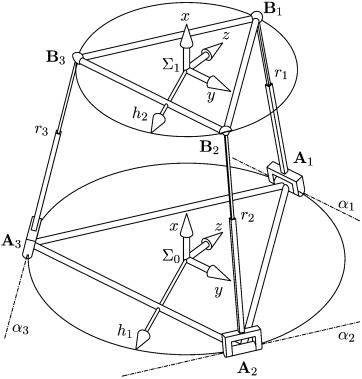

# Seguidor continuo

clear all
close all
%Supongamos valores para las constantes:
const = 0.027 / (0.027 + 4.32e-6 / 0.02^2);
g = 9.81;

a = [ 0  1   0  0;
      0  0  const*g 0;
      0  0   0  1;
      0  0   0  0 ];

b = [ 0;0;0;1];



c = [ 0 0 1 0];


d = zeros(4,1);



% Sistema aumentado con integral en X
Aa = [a, zeros(4,1);
      -[1 0 0 0], 0];
Ba = [b; 0];

% Verificamos controlabilidad
fprintf('size(Aa)=%d, rank(ctrb)=%d\n', size(Aa,1), rank(ctrb(Aa,Ba)));

% Diseñamos controlador LQI
Q = diag([10 10 1 1 100]);  % peso fuerte al integrador
R = 1;
K = lqr(Aa, Ba, Q, R);

% Separar ganancias proporcional e integral
Kp = K(:, 1:4);
Ki = K(:, 5);

fprintf('Kp = \n'); disp(Kp);
fprintf('Ki = \n'); disp(Ki);



% --- Datos del sistema (ya definidos por ti) ---
% a (4x4), b (4x1), c_x = [1 0 0 0]
% Kp (1x4), Ki (scalar) obtenidos antes.

c_x = [1 0 0 0];
Kp = [15.6179, 11.6960, 33.7431, 8.2756];
Ki = -10.0000;

% Construcción de sistema aumentado lazo cerrado:
A11 = a - b * Kp;        % 4x4
A12 = -b * Ki;           % 4x1
A21 = -c_x;              % 1x4
A22 = 0;                 % 1x1

A_cl = [A11, A12;
        A21, A22];       % 5x5

B_cl = [zeros(4,1);
        1];              % entrada = referencia x_ref (because z_dot = x_ref - c_x*x)

% simulación: respuesta a paso en x_ref
tfinal = 5; dt = 0.001;
t = 0:dt:tfinal;
x0 = zeros(4,1); z0 = 0;
X = [x0; z0];

x_ref = 500; % 1 cm paso
Xhist = zeros(5, length(t));
uhist = zeros(1, length(t));

for k = 1:length(t)
    % dinámicas continuas integradas por Euler (suficiente para ver comportamiento)
    Xdot = A_cl * X + B_cl * x_ref;
    X = X + dt * Xdot;
    Xhist(:,k) = X;
    % calcula u = -Kp*x - Ki*z
    x_state = X(1:4);
    z_state = X(5);
    u = -Kp * x_state - Ki * z_state;
    uhist(k) = u;
end

% plots
figure;
subplot(3,1,1);
plot(t, Xhist(1,:)); grid on;
xlabel('t (s)'); ylabel('x (m)'); title('Posición X');

subplot(3,1,2);
plot(t, uhist); grid on;
xlabel('t (s)'); ylabel('u'); title('Señal de control u');

subplot(3,1,3);
plot(t, Xhist(5,:)); grid on;
xlabel('t (s)'); ylabel('z'); title('Estado integrador z');



# Seguidor con Observador Continuo

%% Script: LQI + Observador (comprueba observabilidad y usa place o lqe)
clearvars; close all;

% parámetros
const = 0.027 / (0.027 + 4.32e-6 / 0.02^2);
g = 9.81;

A = [ 0  1   0  0;
      0  0  const*g 0;
      0  0   0  1;
      0  0   0  0 ];
B = [0;0;0;1];

% Control LQI (aquí asumimos integrador en X como antes)
C_x = [1 0 0 0];            % integrador sobre la posición X
Aa = [A, zeros(4,1); -C_x, 0];
Ba = [B; 0];
Q = diag([10 10 1 1 100]); R = 1;
K = lqr(Aa, Ba, Q, R);
Kp = K(:,1:4); Ki = K(:,5);

fprintf('Kp y Ki calculados.\n'); disp(Kp); disp(Ki);

% ---- Elige aquí la matriz de medición real del sensor ----
% Si mides la POSICIÓN de la bola:
% Cmeas = [1 0 0 0];   % MIDE x (recomendado)
% Si mides el ANGULO de la placa (tu caso actual):
Cmeas = [1 0 0 0];     % MIDE theta  (esto da rango observabilidad = 2 en tu salida)
% Puedes probar otras opciones: Cmeas = [1 0 1 0]; etc.

% Diagnóstico de observabilidad
Ob = obsv(A, Cmeas);
rankOb = rank(Ob);
fprintf('Tamaño A = %d, rango(obsv) = %d\n', size(A,1), rankOb);

% Intentar diseñar Luenberger por place si observable
useLqe = false;
if rankOb == size(A,1)
    fprintf('Observable: intentando place para L.\n');
    try
        % polos del observador (más rápidos que lazo cerrado)
        % Elige valores menos agresivos si fallan: [-10 -12 -15 -18]
        p_obs =  [-8 -10 -12 -14];        
        L = place(A', Cmeas', p_obs)'; 
        fprintf('L calculado por place:\n'); disp(L);
    catch ME
        fprintf('place falló: %s\n', ME.message);
        useLqe = true;
    end
else
    fprintf('NO observable con Cmeas. Se usará LQE (si procede) o debes cambiar Cmeas.\n');
    useLqe = true;
end

% Si elegimos lqe (Kalman) como alternativa:
if useLqe
    fprintf('Diseñando L por LQE (Kalman) con Bw = I, Qn y Rn heurísticos.\n');
    Bw = eye(4);
    Qn = 1e-3 * eye(4);   % ajustar según ruido de proceso
    Rn = 1e-2;            % ajustar según ruido de medida (SNR)
    try
        % lqe devuelve la ganancia de filtro (convención puede variar en versiones)
        L_kf = lqe(A, Bw, Cmeas, Qn, Rn); 
        L = L_kf; % en la mayoría de versiones está en la convención correcta
        fprintf('L calculado por LQE:\n'); disp(L);
    catch ME
        warning('lqe falló: %s\nNo se pudo obtener L automáticamente.', E.message);
        L = zeros(size(A)); % placeholder para evitar errores posteriores
    end
end

% ---- Simulación del sistema real + observador + LQI ----

dt = 0.0005; tfinal = 3; t = 0:dt:tfinal;
x = [0.01;0;0.02;0];    % estado real inicial (ejemplo)
x_hat = zeros(4,1);     % estimador
z = 0;
x_ref = 2;

Xreal = zeros(4,length(t)); Xhat = zeros(4,length(t)); U = zeros(1,length(t));
for k = 1:length(t)
    y = Cmeas * x;
    u = -Kp * x_hat - Ki * z;
    % planta
    xdot = A*x + B*u;
    x = x + dt * xdot;
    % observador
    xhatdot = A*x_hat + B*u + L*(y - Cmeas*x_hat);
    x_hat = x_hat + dt * xhatdot;
    % integrador (usa x_hat)
    z = z + dt * (x_ref - C_x * x_hat);
    % logs
    Xreal(:,k) = x; Xhat(:,k) = x_hat; U(k) = u;
end

% Plots
figure;
subplot(3,1,1);
plot(t, Xreal(1,:), 'b', t, Xhat(1,:), 'r--'); grid on;
legend('x real','x estimado'); ylabel('x (m)'); title('Posición y estimación');

subplot(3,1,2);
plot(t, U); grid on; ylabel('u'); title('u');

subplot(3,1,3);
plot(t, Xreal(3,:), 'b', t, Xhat(3,:), 'r--'); grid on;
legend('theta real','theta estimado'); ylabel('theta'); xlabel('t (s)');

% Mensaje final
if rankOb < size(A,1)
    fprintf('\nATENCIÓN: el sistema NO es observable con el C elegido. El observador estimará solo el subespacio observable.\n');
    fprintf('Recomendación: si puedes, cambia Cmeas a medir la POSICIÓN de la bola: Cmeas = [1 0 0 0].\n');
else
    fprintf('\nObservador diseñado por place con polos %s\n', mat2str(p_obs));
end





# Seguidor Discreto

%% Datos continuos (tus matrices)
close all
clearvars

const = 0.027 / (0.027 + 4.32e-6 / 0.02^2);
g = 9.81;
a = [ 0  1   0  0;
      0  0  const*g 0;
      0  0   0  1;
      0  0   0  0 ];
b = [0;0;0;1];
c_x = [1 0 0 0];

% Sistema aumentado continuo
Aa = [a, zeros(4,1);
      -c_x, 0];
Ba = [b; 0];

Ts = 0.01;
sysc = ss(Aa, Ba, eye(5), zeros(5,1));
sysd = c2d(sysc, Ts, 'zoh');
Ad = sysd.A;
Bd = sysd.B;


Q = diag([0.1, 0.1, 1, 1, 100]);
R = 800; %nota probar esta config
Kd = dlqr(Ad, Bd, Q, R);
Kp_d = Kd(:,1:4);
Ki_d = Kd(:,5);

format long
fprintf('\nfloat Kp_d[4] = { %0.15f, %0.15f, %0.15f, %0.15f };\n', Kp_d);


float Kp_d[4] = { 0.938355053193236, 1.269478513267976, 7.438397351672183, 3.847147542468491 };


fprintf('float Ki_d = %0.15f;\n', Ki_d);

float Ki_d = -0.346752607179130;


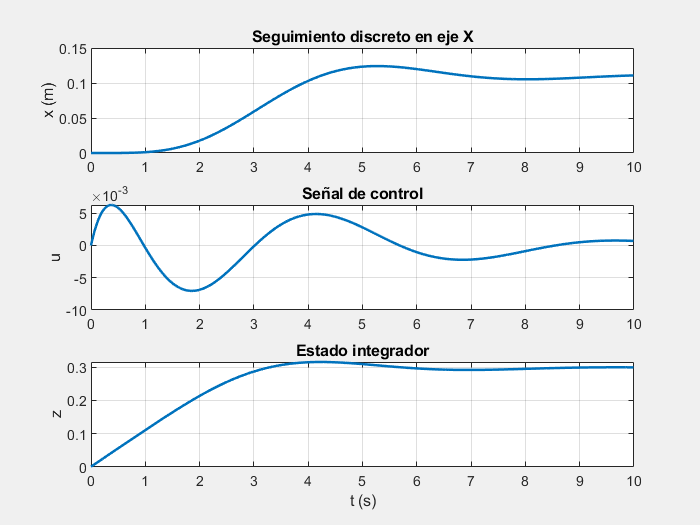


% --- Simulación ---
Nsim = 1000;
x = zeros(4,1);
z = 0;
Xhist = zeros(5, Nsim);
uhist = zeros(1, Nsim);
t = (0:Nsim-1)*Ts;

x_ref = 0.11;   % 1 cm
u_min = -5; u_max = 5;

for k = 1:Nsim
    % Control
    u = -Kp_d * x - Ki_d * z;
    u = min(max(u, u_min), u_max);
    uhist(k) = u;

    % Propagar dinámica discreta (solo las 4 primeras filas)
    x_next = Ad(1:4,1:4)*x + Ad(1:4,5)*z + Bd(1:4)*u;

    % Integrador explícito sobre el error (para seguimiento de referencia)
    z = z + Ts*(x_ref - x(1));

    x = x_next;
    Xhist(:,k) = [x; z];
end

% --- Gráficas ---
f = figure(1);
set(f, 'Visible', 'on');
subplot(3,1,1);
plot(t, Xhist(1,:), 'LineWidth',1.5); grid on;
ylabel('x (m)'); title('Seguimiento discreto en eje X');
subplot(3,1,2);
plot(t, uhist, 'LineWidth',1.5); grid on;
ylabel('u'); title('Señal de control');
subplot(3,1,3);
plot(t, Xhist(5,:), 'LineWidth',1.5); grid on;
ylabel('z'); xlabel('t (s)'); title('Estado integrador');

# Seguidor Discreto con Observador

clearvars; close all;

SIMULACION = 1;

% parámetros
const = 0.027 / (0.027 + 4.32e-6 / 0.02^2);
g = 9.81;

A = [ 0  1   0  0;
      0  0  const*g 0;
      0  0   0  1;
      0  0   0  0 ];
B = [0;0;0;1];

C_x = [1 0 0 0];
Cmeas = [1 0 0 0];  

Ts = 0.01;            % 10 ms


% sistema continuo:
Aa = [A, zeros(4,1); -C_x, 0];
Ba = [B; 0];

% opción A: discretizar el sistema aumentado (si quieres dlqr)
sysc = ss(Aa, Ba, eye(size(Aa)), zeros(size(Aa,1),1));
sysd = c2d(sysc, Ts, 'zoh');
Ad = sysd.A;
Bd = sysd.B; % Ad es 5x5, Bd 5x1


% dlqr discreto (si quieres rediseñar en discreto)
Qd = diag([0.1,0.01,1,1,1]); 
Rd = 150;
Kd = dlqr(Ad, Bd, Qd, Rd);   % 1x5
Kp_d = Kd(:,1:4); Ki_d = Kd(:,5);

% Para el observador en discreto: discretiza (A,C) y coloca polos discreto
Ad_cont = A; Bd_cont = B; Cd = Cmeas;
sysc_plant = ss(Ad_cont, Bd_cont, Cd, 0);
sysd_plant = c2d(sysc_plant, Ts, 'zoh');
Ad_p = sysd_plant.A;
Bd_p = sysd_plant.B;
Cd_p = sysd_plant.C;

% elige polos discretos razonables (ej: polos cont. -8,-10,-12,-14 -> discretizar)
p_obs_cont = 0.5*[-8 -10 -12 -14];
p_obs_disc = exp(p_obs_cont * Ts);  % z = e^{p Ts}
% colocar Ld (dual): place(Ad', C', p_obs_disc)'
Ld = place(Ad_p', Cd_p', p_obs_disc)';


format long



# PRINTS ESP


%fprintf('\n// ---------------------- Ganancias del observador ------------------------\n');
fprintf('double LdX[4] = {\n');
fprintf('    %0.15f,\n    %0.15f,\n    %0.15f,\n    %0.15f\n};\n', Ld);
%fprintf('\ndouble LdY[4] = {\n');
%fprintf('    %0.15f,\n    %0.15f,\n    %0.15f,\n    %0.15f\n};\n', Ld);
%fprintf('\n// --- Ganancias del controlador LQI ---\n');
%fprintf('double Kp_dX[4] = { %0.15f, %0.15f, %0.15f, %0.15f };\n', Kp_d);
%fprintf('double Ki_dX = %0.15f;\n', Ki_d);
%fprintf('\ndouble Kp_dY[4] = { %0.15f, %0.15f, %0.15f, %0.15f };\n', Kp_d);
%fprintf('double Ki_dY = %0.15f;\n', Ki_d);



# SIMULACIÓN


%% Simulación discreta

Tfinal = 10;
N = round(Tfinal/Ts);
x_ref = 0.5;

%x = [1; 0; 0; 0];      % por ejemplo, posición inicial 120, velocidades 0
%x_hat = [0.5; 0; 0; 0];  % estimación inicial diferente

x = [0; 0; 0; 0];      % por ejemplo, posición inicial 120, velocidades 0
x_hat = [0; 0; 0; 0];  % estimación inicial diferente


%x = zeros(4,1);      % estado real
%x_hat = zeros(4,1);  % estado estimado
z = 0;               % integrador
u_hist = zeros(1,N);
x_hist = zeros(4,N);
xhat_hist = zeros(4,N);
z_hist = zeros(1,N);

for k = 1:N
    % error integrador
    z = z + Ts*(x_ref - Cd*x_hat);

    % Control LQI discreto
    u = -Kp_d*x_hat - Ki_d*z;
    
    % Dinámica del sistema (discreto simple)
    x = Ad_p*x + Bd_p*u;   % sistema sin integrador

    % Observador discreto
    x_hat = Ad_p*x_hat + Bd_p*u + Ld*(Cd*x - Cd*x_hat);
    
    % Guardar historiales
    u_hist(k) = u;
    x_hist(:,k) = x;
    xhat_hist(:,k) = x_hat;
    z_hist(k) = z;
end

%% Graficar resultados
t = (0:N-1)*Ts;
f = figure(1);
set(f, 'Visible', 'on');
subplot(3,1,1);
plot(t, x_hist(1,:), 'b', 'LineWidth', 1.5); hold on;
plot(t, xhat_hist(1,:), 'r--', 'LineWidth', 1.2);
xlabel('t [s]'); ylabel('x_1'); grid on;
legend('Real', 'Estimado'); title('Posición X');

subplot(3,1,2);
plot(t, u_hist, 'k', 'LineWidth', 1.5);
xlabel('t [s]'); ylabel('u'); grid on;
title('Señal de control');

subplot(3,1,3);
plot(t, z_hist, 'm', 'LineWidth', 1.5);
xlabel('t [s]'); ylabel('z'); grid on;
title('Estado integrador');






if(SIMULACION) 
    BallAndPlateSimulink
end

